# Gaze-biases

## Housekeeping

### Load Data

The mat file loaded in, below, contains the tables rquired to assess gaze biases. Note that the data has been truncated to account for terminal NDT (see text for details)

- gazeBias: data from standard sessions

- soa: data from gaze-manipulation sessions

clear; close all; clc
load GazeBiases.mat

### Variable Definitions

The following variables are present in both tables:

- firstFixIsLeft: logical indicator as to whether the first fixation was to left (true) or right (false) target 

- chosen: which target was chosen (1 = left, 0 = right)

- vDiff: left value - right value

- session: session identifier

- monk: monkey identifier

The following variables are only present in the *gazeBias *table:

- timeAdv: time advantage for the left item, computed as (total dwell time left - total dwell time right)

- totFix: total number of fixations in the trial

- lastFixIsLeft: logical indicator as to whether the final fixation was to left (true) or right (false) target 

- correctProb: probability of choosing the left item after correcting for value (see text for details)

% for the cumulative gaze-time bias and the final fixation bias, analyses
% do not include trials with only a single fixation. Here we create an
% index of single fixation trials
sing = gazeBias.totFix == 1;

The following variable is only present in the soa table:

- condition: logical indicator denoting whether the stimulus onset was staggered (true) or the targets appeared simultaneously (false)

## Initial Fixation Bias

### Analysis

#### Standard Sessions

% initial fixation bias: mixed effects model
firstFix = fitglme(gazeBias,'chosen ~ vDiff + firstFixIsLeft +(vDiff + firstFixIsLeft|monk)','Distribution','Binomial')

firstFix = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30046
    Fixed effects coefficients           3
    Random effects coefficients          6
    Covariance parameters                6
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + firstFixIsLeft + (1 + vDiff + firstFixIsLeft | monk)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.6501e+05    1.6508e+05    -82496           1.6499e+05

Fixed effects coefficients (95% CIs):
    Name                        Estimate    SE          tStat      DF       pValue        Lower       Upper   
    {'(Intercept)'     }        -0.35196    0.031389    -11.213    30043    4.0272e-29    -0.41349    -0.29044
    {'vDiff'           }          1.3998

% ratio of the firstFixIsLeft coefficient to the vDiff coefficient. Taken as a metric of the change in subjective value attributable to the direction of the first fixation
double(firstFix.Coefficients(3,2))/double(firstFix.Coefficients(2,2))

ans = 0.4729

% run anova on the output of the model
firstFixAnova = anova(firstFix)

firstFixAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                      FStat     DF1    DF2      pValue    
    {'(Intercept)'   }        125.73    1      30043    4.0272e-29
    {'vDiff'         }        5349.4    1      30043             0
    {'firstFixIsLeft'}         14.36    1      30043     0.0001513


#### Gaze-Manipulation Sessions

% gaze-manipulation aka, stimulus onset asynchrony (soa):
% mixed effects model
soaModel = fitglme(soa,'chosen~ vDiff + firstFixIsLeft*condition + (1 + vDiff + firstFixIsLeft*condition|monk)','Distribution',"Binomial")

soaModel = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           12364
    Fixed effects coefficients           5
    Random effects coefficients         10
    Covariance parameters               15
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + firstFixIsLeft*condition + (1 + vDiff + firstFixIsLeft*condition | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    64610    64758    -32285           64570   

Fixed effects coefficients (95% CIs):
    Name                                    Estimate     SE          tStat       DF       pValue        Lower       Upper   
    {'(Intercept)'                 }         -0.25027     0.15594     -1.6049    12359       0.10853    -0.55593    0.055391
    {'firstFixIs

% ratio of the firstFixIsLeft coefficient to the vDiff coefficient. Taken as a metric of the change in subjective value attributable to the direction of the first fixation
double(soaModel.Coefficients(2,2))/double(soaModel.Coefficients(3,2))

ans = 0.5702

%run anova on the output of the model
soaAnova= anova(soaModel)

soaAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                                FStat         DF1    DF2      pValue    
    {'(Intercept)'             }            2.5758    1      12359       0.10853
    {'firstFixIsLeft'          }            21.825    1      12359    3.0182e-06
    {'vDiff'                   }            560.84    1      12359    2.712e-121
    {'condition'               }           0.32154    1      12359       0.57069
    {'firstFixIsLeft:condition'}        0.00015192    1      12359       0.99017


### Plot Results

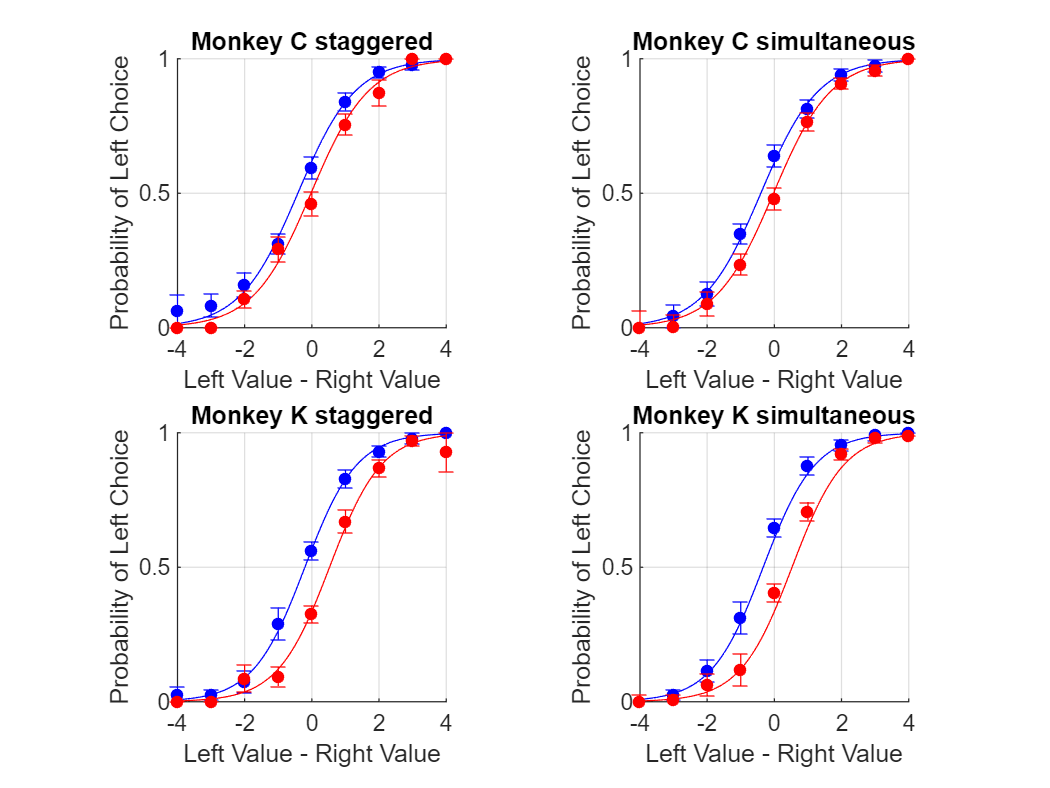

% get session-wise metrics
monks = {'claudio','kirby'};
xChoice = linspace(-4,4,81)';
idx =[1:81; 82:162];
idx2 = [1:41; 42:82];

clf
soaChoice = grpstats(soa,{'session','condition','vDiff','monk','firstFixIsLeft'},{'mean'},...
    'DataVars','chosen');

soaChoice2 = grpstats(soaChoice,{'condition','vDiff','monk','firstFixIsLeft'},{'mean','sem'},...
    'DataVars',{'mean_chosen'});
x = repmat([-4:0.1:4]',[2 1]);
xPredSOA_left = soa(find(soa.condition == 1,162,"first"),:);
xPredSOA_left.vDiff = x;
xPredSOA_left.firstFixIsLeft = logical(ones(162,1));
xPredSOA_left.monk(82:end) = "kirby";
xPredSOA_right = soa(1:162,:);
xPredSOA_right.vDiff = x;
xPredSOA_right.monk(82:end) = "kirby";
xPredSOA_right.firstFixIsLeft = logical(zeros(162,1));
SOAYhat_left = predict(soaModel,xPredSOA_left);
SOAYhat_right = predict(soaModel,xPredSOA_right);

xPredNonSOA_left = soa(find(~soa.condition,162,"first"),:);
xPredNonSOA_left.vDiff = x;
xPredNonSOA_left.firstFixIsLeft = logical(ones(162,1));
xPredNonSOA_left.monk(82:end) = "kirby";
xPredNonSOA_right = soa(1:162,:);
xPredNonSOA_right.vDiff = x;
xPredNonSOA_right.monk(82:end) = "kirby";
xPredNonSOA_right.firstFixIsLeft = logical(zeros(162,1));
nonSOAYhat_left = predict(soaModel,xPredNonSOA_left);
nonSOAYhat_right = predict(soaModel,xPredNonSOA_right);



%% plot initial fixation bias SOA
monkeys = {'Monkey C','Monkey K'};
for monk = 1:2
    % soa curve
    subplot(2,2,monk*2-1)
    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).sem_mean_chosen,'Color','b',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,SOAYhat_left(idx(monk,:)),'color','b')

    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & logical(soaChoice2.condition) & soaChoice2.firstFixIsLeft == 0,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft == 0,:).sem_mean_chosen,'Color','r',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,SOAYhat_right(idx(monk,:)),'color','r')
    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    ylim([0 1])
    xlim([-4 4])
    title([monkeys{monk},' staggered'])
    set(gca,'XGrid',1,'YGrid',1)
    pbaspect([1 1 1])
    box off
    yticks([0 0.5 1])

    % non-SOA curve
    subplot(2,2,monk*2)
    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & ~soaChoice2.condition & soaChoice2.firstFixIsLeft,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).sem_mean_chosen,'Color','b',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,nonSOAYhat_left(idx(monk,:)),'color','b')


    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & ~soaChoice2.condition & soaChoice2.firstFixIsLeft == 0,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).sem_mean_chosen,'Color','r',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,nonSOAYhat_right(idx(monk,:)),'color','r')


    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    title([monkeys{monk} ,' simultaneous'])
    ylim([0 1])
    xlim([-4 4])
    yticks([0 0.5 1])
    set(gca,'XGrid',1,'YGrid',1)
    pbaspect([1 1 1])
    box off
end

## Final Fixation Bias

### Analysis

% final fixation bias: mixed effects model
lastFix = fitglme(gazeBias(~sing,:),'chosen ~ vDiff + lastFixIsLeft +(vDiff + lastFixIsLeft|monk)','Distribution','Binomial')

lastFix = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           28395
    Fixed effects coefficients           3
    Random effects coefficients          6
    Covariance parameters                6
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + lastFixIsLeft + (1 + vDiff + lastFixIsLeft | monk)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance 
    1.7621e+05    1.7629e+05    -88098           1.762e+05

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE          tStat      DF       pValue        Lower      Upper  
    {'(Intercept)'    }        -1.9539      0.45568    -4.2879    28392    1.8094e-05    -2.8471    -1.0608
    {'vDiff'          }         1.2815     0.018518

% run anova on the output of the model
lastFixAnova = anova(lastFix)

lastFixAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                     FStat     DF1    DF2      pValue    
    {'(Intercept)'  }        18.386    1      28392    1.8094e-05
    {'vDiff'        }        4789.3    1      28392             0
    {'lastFixIsLeft'}        41.995    1      28392    9.2992e-11


### Plot Results

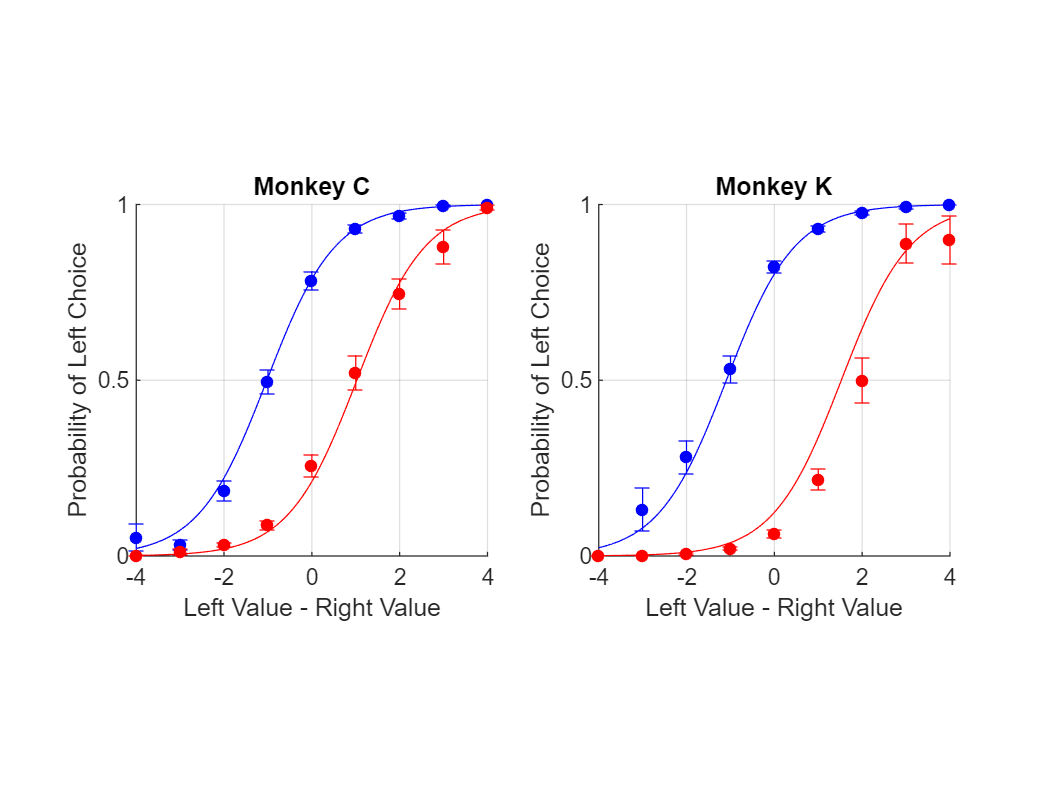

lastFixChoice = grpstats(gazeBias(~sing,:),{'session','vDiff','monk','lastFixIsLeft'},{'mean'},...
    'DataVars','chosen');
lastFixChoice2 = grpstats(lastFixChoice,{'vDiff','monk','lastFixIsLeft'},{'mean','sem'},...
    'DataVars',{'mean_chosen'});


% get variables for gaze biases
monkeys = {'Monkey C','Monkey K'};
% final fixation bias
xPredlastFix_left = gazeBias(1:162,:);
xPredlastFix_left.vDiff = x;
xPredlastFix_left.lastFixIsLeft = logical(ones(162,1));
xPredlastFix_left.monk(82:end) = "MonkeyK";
xPredlastFix_right = gazeBias(1:162,:);
xPredlastFix_right.vDiff = x;
xPredlastFix_right.monk(82:end) = "MonkeyK";
xPredlastFix_right.lastFixIsLeft = logical(zeros(162,1));
lastFixYhat_left = predict(lastFix,xPredlastFix_left);
lastFixYhat_right = predict(lastFix,xPredlastFix_right);


%% plot final fixation bias
clf
for monk = 1:2
    % choice curve
    subplot(1,2,monk)


    errorbar(-4:4,lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft,:).mean_mean_chosen, ...
        lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft,:).sem_mean_chosen,'Color','b',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,lastFixYhat_left(idx(monk,:)),'color','b')


    errorbar(-4:4,lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft == 0,:).mean_mean_chosen, ...
        lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft == 0,:).sem_mean_chosen,'Color','r',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,lastFixYhat_right(idx(monk,:)),'color','r')

    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    title(monkeys{monk})
    ylim([0 1])
    xlim([-4 4])
    yticks([0 0.5 1])
    set(gca,'XGrid',1,'YGrid',1)
    pbaspect([1 1 1])
    box off
end

## Cumulative Gaze-Time Bias 

### Analysis

#### Standard Probability

% cumulative gaze-time bias: mixed effects model
timeAdv = fitglme(gazeBias(~sing,:),'chosen ~ timeAdv +(1 + timeAdv|monk)','Distribution','Binomial')

timeAdv = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           28395
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                3
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + timeAdv + (1 + timeAdv | monk)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    3.739e+05    3.7394e+05    -1.8694e+05      3.7389e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue        Lower       Upper  
    {'(Intercept)'}        -0.06595    0.12188    -0.5411    28393       0.58844    -0.30485    0.17294
    {'timeAdv'    }          18.706     1.8543     10.088    28393    6.8634e-24      1

% run anova on the output of the model
timeAdvAnova = anova(timeAdv)

timeAdvAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2      pValue    
    {'(Intercept)'}        0.29279    1      28393       0.58844
    {'timeAdv'    }         101.76    1      28393    6.8634e-24


#### Value-Corrected Choice Probabilities

% cumulative gaze-time bias with corrected probabilities:
% mixed effects model
timeAdvC = fitglme(gazeBias(~sing,:),'correctProb ~ timeAdv +(1 + timeAdv|monk)','Distribution','Normal')

timeAdvC = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           28395
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    correctProb ~ 1 + timeAdv + (1 + timeAdv | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14394    14443    -7190.9          14382   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF       pValue        Lower        Upper   
    {'(Intercept)'}        0.0021233    0.0046276    0.45883    28393       0.64636    -0.006947    0.011194
    {'timeAdv'    }            1.067     0.073821     14.453    28393    3.5175e-47      0.92

% run anova on the output of the model
timeAdvCAnova = anova(timeAdvC)

timeAdvCAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2      pValue    
    {'(Intercept)'}        0.21052    1      28393       0.64636
    {'timeAdv'    }          208.9    1      28393    3.5175e-47


### Plot Results

% for plotting, we remove outliers.
gazeBias2 = gazeBias(~sing,:);

for m = 1:2
    upperBound{m} = nanmean([gazeBias2.timeAdv(gazeBias2.monk==monks{m})])+(3*nanstd([gazeBias2.timeAdv(gazeBias2.monk==monks{m})]));
    lowerBound{m} = nanmean([gazeBias2.timeAdv(gazeBias2.monk==monks{m})])-(3*nanstd([gazeBias2.timeAdv(gazeBias2.monk==monks{m})]));
    outlierIdx{m} = ([gazeBias2.timeAdv(gazeBias2.monk==monks{m})] >= upperBound{m}) | ([gazeBias2.timeAdv(gazeBias2.monk==monks{m})] <= lowerBound{m});
    disp(['# of outlier trials for  ', monks{m}, ': ', num2str(sum(outlierIdx{m})),', ',num2str(mean(outlierIdx{m})*100) '% of trials'])
end

# of outlier trials for  claudio: 95, 0.62603% of trials
# of outlier trials for  kirby: 50, 0.37821% of trials


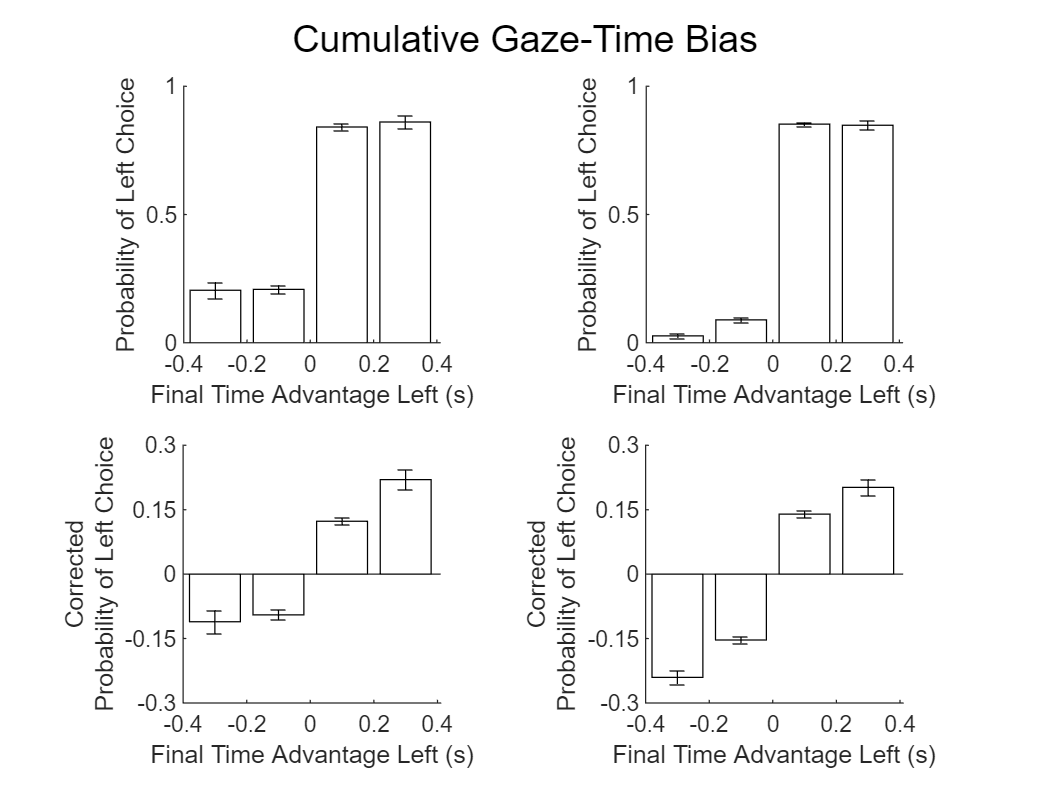

outliers = [outlierIdx{1};outlierIdx{2}];
gazeBias2(outliers,:) = [];

edges = [-0.4:0.2:0.4];
[N, edge, bins] = histcounts(gazeBias2.timeAdv,edges);
gazeBias2.Id=bins;

close all
gazeBias2.session = categorical(gazeBias2.session);
gazeBias2.monk = categorical(gazeBias2.monk);

centers = [edge+ 0.1];

timeAdvChosen = grpstats(gazeBias2,{'session','monk','Id'},{'mean'},...
    'DataVars','chosen');
timeAdvChosen2 = grpstats(timeAdvChosen,{'monk','Id'},{'mean','sem'},...
    'DataVars','mean_chosen');
timeAdvChosenC = grpstats(gazeBias2,{'session','monk','Id'},{'mean'},...
    'DataVars','correctProb');
timeAdvChosenC2 = grpstats(timeAdvChosenC,{'monk','Id'},{'mean','sem'},...
    'DataVars','mean_correctProb');
clf
for mm = 1:2

    subplot(2,2,mm)
    bar(centers(1:end-1),timeAdvChosen2(timeAdvChosen2.monk == monks{mm},:).mean_mean_chosen, 'FaceColor','none', 'LineWidth',0.5);hold on
    errorbar(centers(1:end-1),timeAdvChosen2(timeAdvChosen2.monk == monks{mm},:).mean_mean_chosen, ...
        timeAdvChosen2(timeAdvChosen2.monk == monks{mm},:).sem_mean_chosen,'Color','k',...
        'LineStyle', 'none', 'Marker', "none", 'LineWidth', 0.5)


    ylabel('Probability of Left Choice')
    box off
    ylim([0 1])
    yticks([0 0.5 1])
    xlim([-0.4 0.41])

    ylabel('Probability of Left Choice')
    xlabel('Final Time Advantage Left (s)')
    pbaspect([1 1 1])

    subplot(2,2,mm+2)
    bar(centers(1:end-1),timeAdvChosenC2(timeAdvChosenC2.monk == monks{mm},:).mean_mean_correctProb,'FaceColor','none', 'LineWidth',0.5);hold on
    errorbar(centers(1:end-1),timeAdvChosenC2(timeAdvChosenC2.monk == monks{mm},:).mean_mean_correctProb, ...
        timeAdvChosenC2(timeAdvChosenC2.monk == monks{mm},:).sem_mean_correctProb,'Color','k',...
        'LineStyle','none','Marker',"none", 'LineWidth',0.5);

    xlabel('Final Time Advantage Left (s)')
    ylim([-0.3 0.3])
    yticks(-0.3:0.15:0.3)
    ylabel({'Corrected';'Probability of Left Choice'})
    box off
    pbaspect([1 1 1])
    xlim([-0.4 0.41])
    sgtitle('Cumulative Gaze-Time Bias')
end